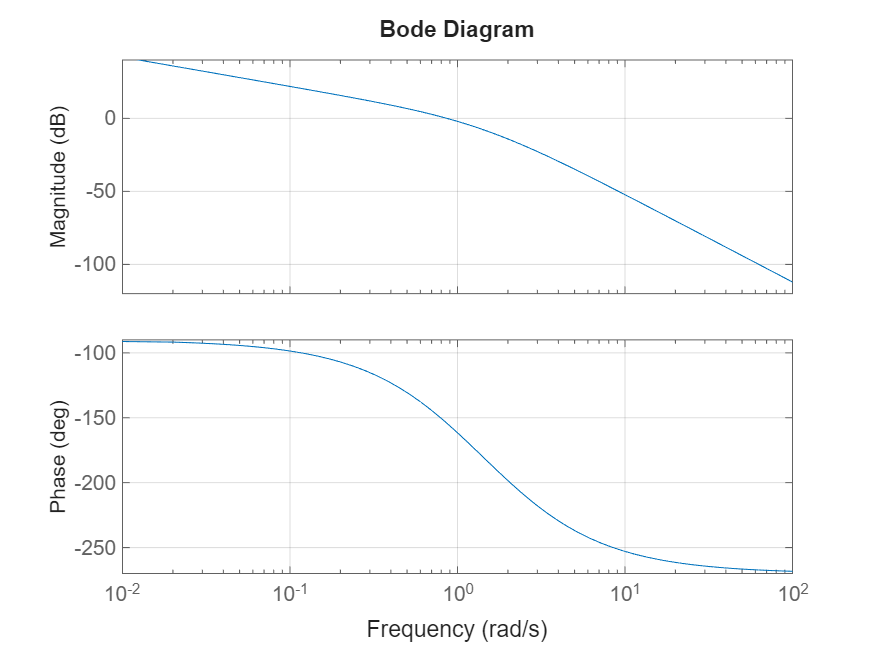

%L1.c. Stability Analysis

% Problem 1
% Determine the stability of the negative unity feedback system
% whose open loop transfer function is given by
% G(s)=1.25/(s(s+1)(0.5s+1))

% Numerator coefficient
a=[1.25];
% Denominator coefficients for s(s+1)
b=[1 1 0];
% Denominator coefficients for (0.5s+1)
c=[0.5 1];
% Overall denominator
d=conv(b,c);
% Bode plot
figure(1)
bode(a,d)
grid on

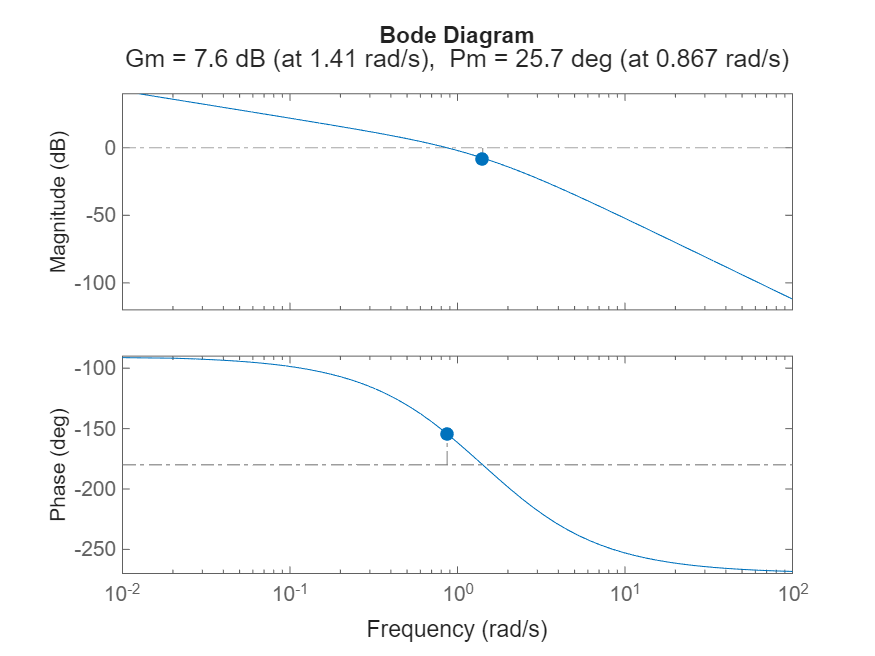

% Gain margin and phase margin
margin(a,d)

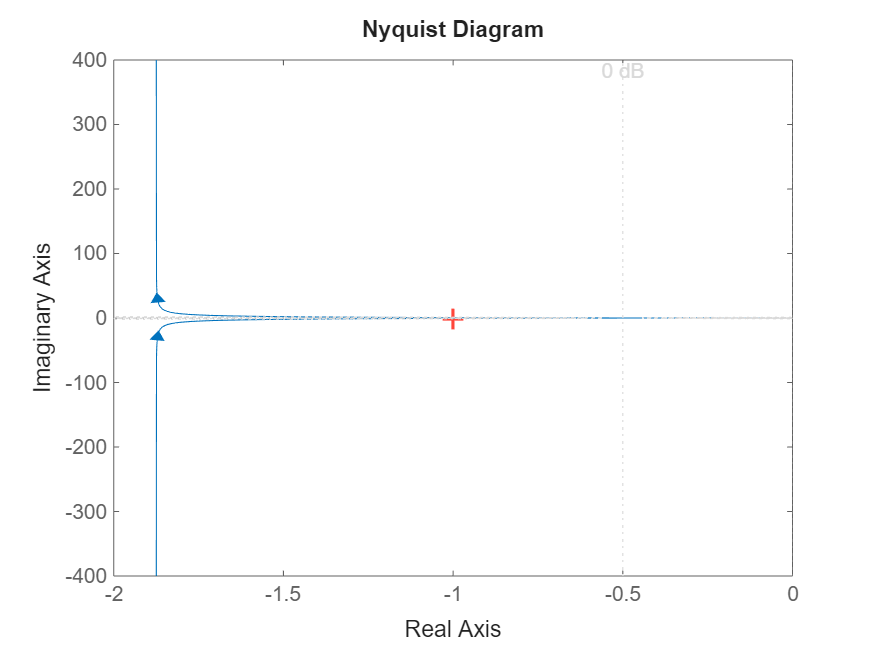

% Nyquist plot
figure(2)
nyquist(a,d)
grid on

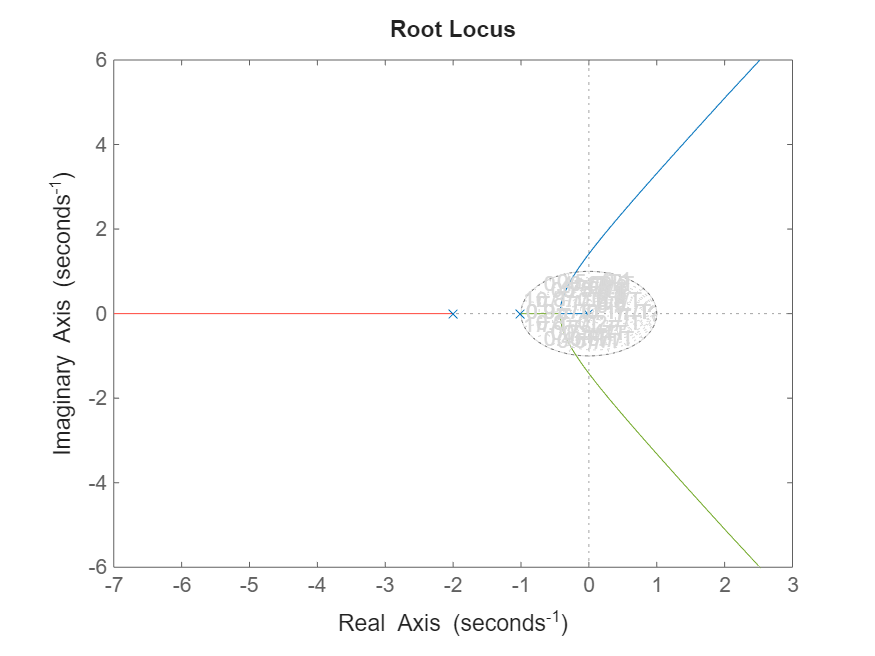

% Root locus
figure(3)
rlocus(a,d)
grid on

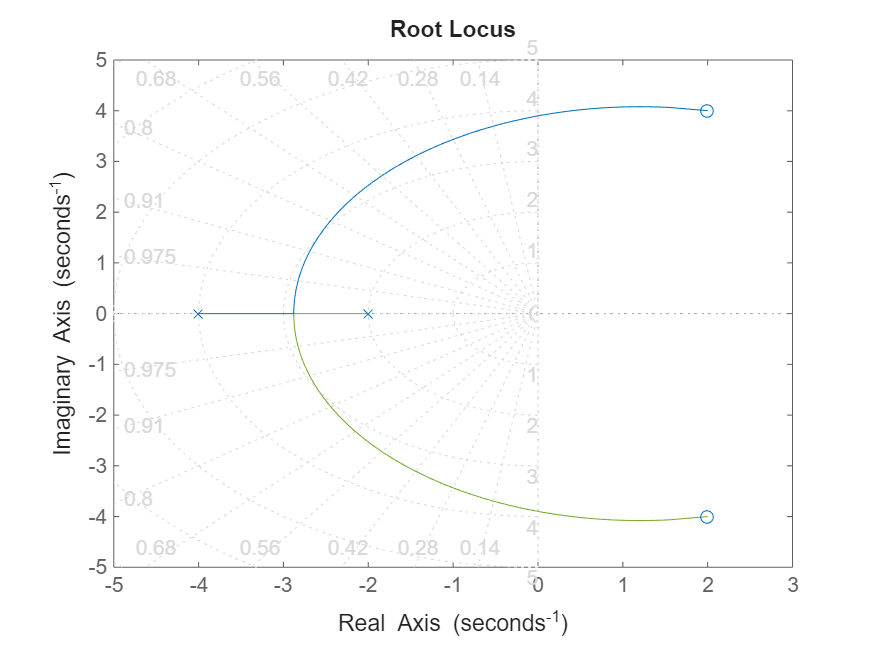

%L1.c. Stability Analysis

% Problem 2
% Sketch the root locus for the system
% G(s)H(s)=K(s^2-4s+20)/((s+2)(s+4))
% Find:
% a) Point and gain where locus crosses zeta=0.45 line
% b) Point and gain where locus crosses imaginary axis
% c) Breakaway point on real axis
% d) Range of K for stability

% Numerator coefficients
numgh=[1 -4 20];
% Denominator coefficients
dengh=poly([-2 -4]);
% Transfer function
GH=tf(numgh,dengh);
% Root locus with damping ratio grid
figure(1)
rlocus(GH)
z=0.2:0.05:0.5;
wn=0:1:10;
sgrid(z,wn)
grid on

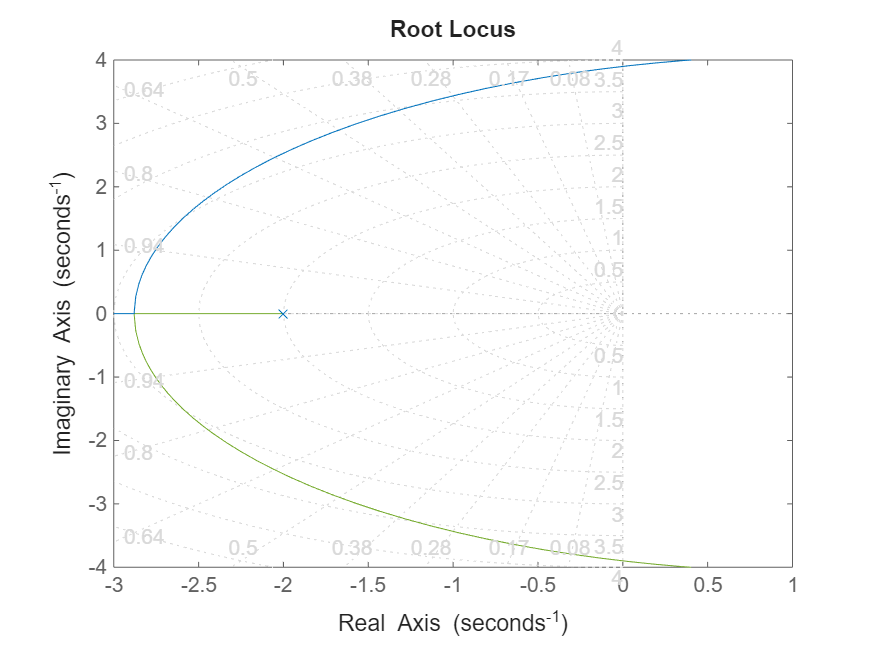

% Root locus for zeta=0.45
figure(2)
rlocus(GH)
axis([-3 1 -4 4])
z=0.45;
wn=0;
sgrid(z,wn)

Select a point in the graphics window


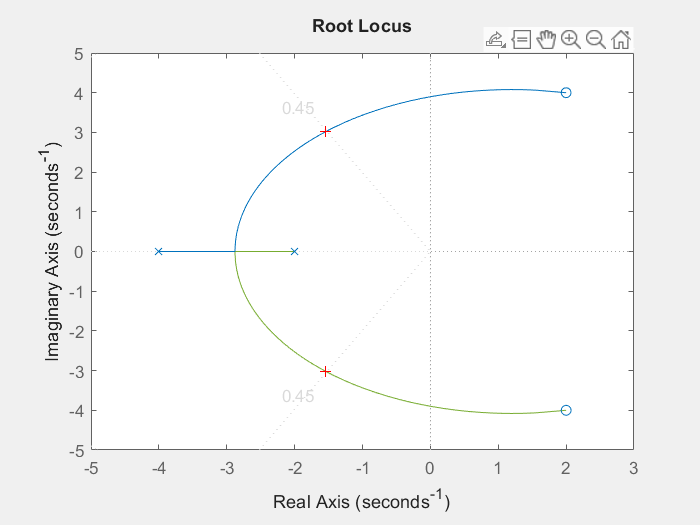

selected_point = -1.5157 + 2.9975i

k = 0.4129

p =   -1.5388 + 3.0231i
  -1.5388 - 3.0231i


% Select point where locus crosses zeta=0.45 line
[k,p]=rlocfind(GH)

% Closed-loop poles
for i=1:length(p)
    p(i)
end

ans = -1.5388 + 3.0231i

ans = -1.5388 - 3.0231i

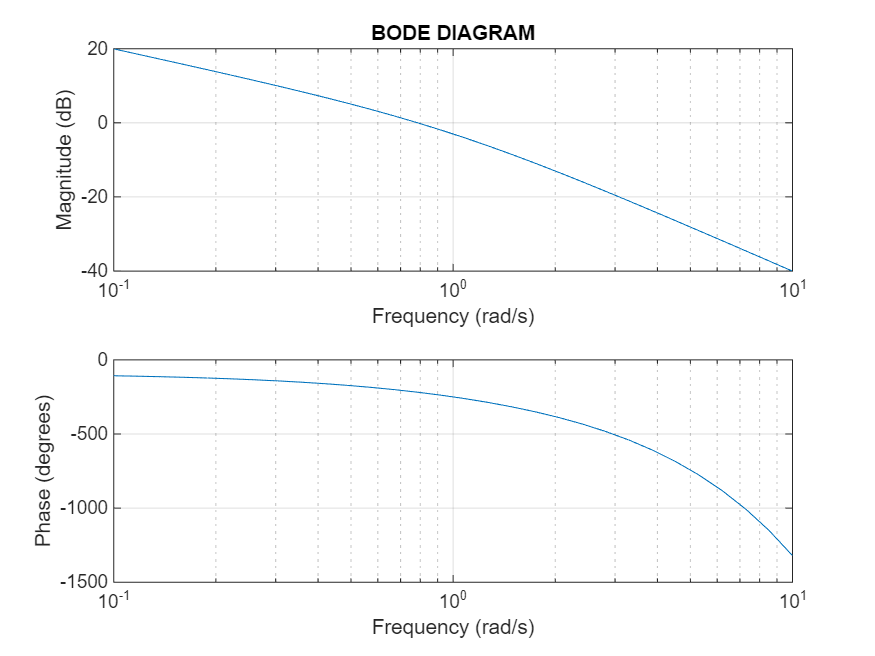

%L1.c. Stability Analysis

% Exercise 1
% Draw Bode diagram for the transfer function
% G(s)=e^(-2s)/(s(s+1))
% Determine the stability

% Frequency range
a=-1;
b=1;
nn=30;
w=logspace(a,b,nn);

% Transfer function coefficients for 1/(s(s+1))
Gnum=[1];
Gden=[1 1 0];
% Magnitude and phase response
[mag,phase,w]=bode(Gnum,Gden,w);
% Convert magnitude to dB
db=20*log10(squeeze(mag));
% Convert phase to vector
phase=squeeze(phase);
% Additional phase due to delay e^(-2s)
phased1=-2*57.296*w;
% Total phase
phase=phase+phased1;
% Bode magnitude plot
subplot(2,1,1)
semilogx(w,db)
title('BODE DIAGRAM')
xlabel('Frequency (rad/s)')
ylabel('Magnitude (dB)')
grid on
% Bode phase plot
subplot(2,1,2)
semilogx(w,phase)
xlabel('Frequency (rad/s)')
ylabel('Phase (degrees)')
grid on

%L1.c. Stability Analysis

% Exercise 2
% Obtain the polar and Nyquist plot of the system having
% G(s)H(s)=k/(s(s+0.5)(s+2))
% Also determine gain crossover frequency, phase margin,
% phase crossover frequency and gain margin

% Open loop gain
k=input('Enter the value of open loop gain k = ');
% Open loop poles
pol=input('Enter three open loop poles [p1 p2 p3] = ');
% Numerator coefficient
n=k;
% Denominator coefficients
d=poly(pol);
% Open loop transfer function
sol=tf(n,d);
% Nyquist data
[re,im,w]=nyquist(sol);
% Magnitude
mag=sqrt(re(:).^2+im(:).^2);
% Magnitude in dB
magdb=20*log10(mag);
% Phase in degrees
phd=(180/pi)*atan2(im(:),re(:));
% Display frequency response data
c=[w magdb phd];
disp(c)
% Polar plot
figure(1)
plot(re(:),im(:))
title('Polar Plot')
xlabel('Real Axis')
ylabel('Imaginary Axis')
grid on
% Nyquist plot
figure(2)
plot(re(:),im(:),re(:),-im(:))
title('Nyquist Plot')
xlabel('Real Axis')
ylabel('Imaginary Axis')
grid on
% Unit circle
[x,y]=scircle1(0,0,1);
hold on
plot(x,y)
% Nyquist plot using MATLAB command
figure(3)
nyquist(n,d)
grid on
% Gain margin, phase margin and crossover frequencies
figure(4)
margin(n,d)
grid on
% Open loop transfer function
oltf=tf(n,d);
% Closed loop transfer function
cltf=feedback(oltf,1);
% Closed loop numerator and denominator
[ncl,dcl]=tfdata(cltf,'v');
% Closed loop poles
clpoles=pole(cltf)

%L1.c. Stability Analysis

% Exercise 3(i)
% Obtain the Nyquist plot and determine the stability
% G(s)=15(s+5)/(s(s+2)(s^2+6s+15))

% Numerator coefficients
num=[15 75];
% Denominator coefficients
den=conv([1 0],[1 2]);
den=conv(den,[1 6 15]);
% Open loop transfer function
G=tf(num,den);
% Nyquist plot
figure(1)
nyquist(G)
grid on
% Gain margin and phase margin
figure(2)
margin(G)
grid on
% Closed loop transfer function
CL=feedback(G,1);
% Closed loop poles
clpoles=pole(CL)

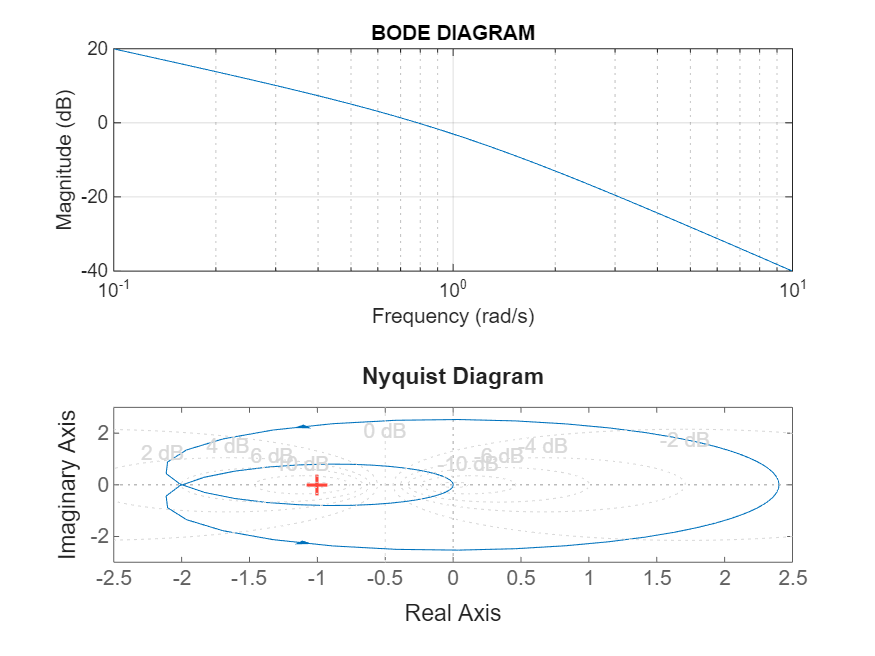

%L1.c. Stability Analysis 

% Exercise 3(ii)
% Obtain the Nyquist plot and determine the stability
% G(s)=12(s+2)/(s^2-6s+10)

% Numerator coefficients
num=[12 24];
% Denominator coefficients
den=[1 -6 10];
% Open loop transfer function
G=tf(num,den);
% Nyquist plot
figure(1)
nyquist(G)
grid on

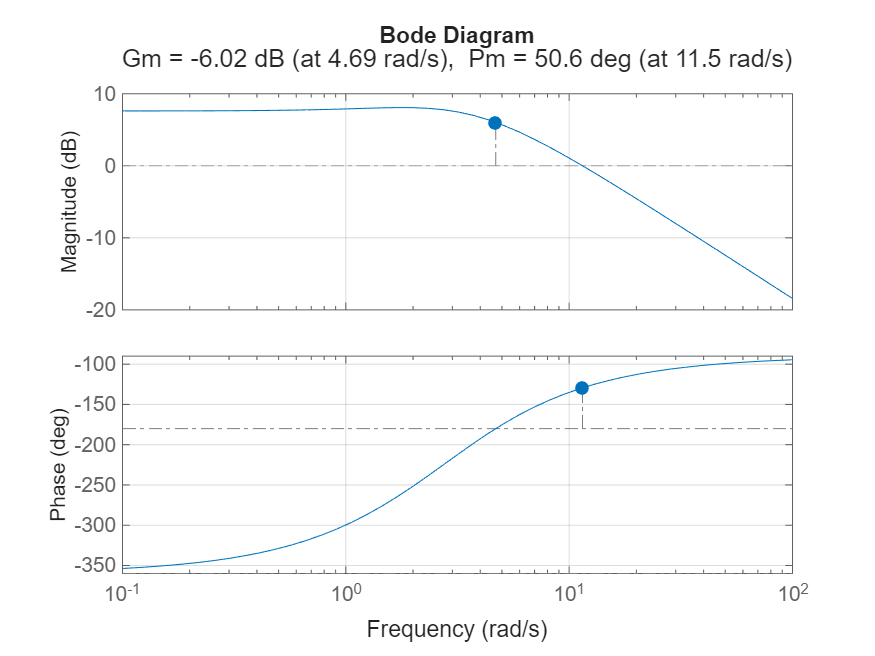

% Gain margin and phase margin
figure(2)
margin(G)
grid on

% Closed loop transfer function
CL=feedback(G,1);
% Closed loop poles
clpoles=pole(CL)

clpoles =   -3.0000 + 5.0000i
  -3.0000 - 5.0000i


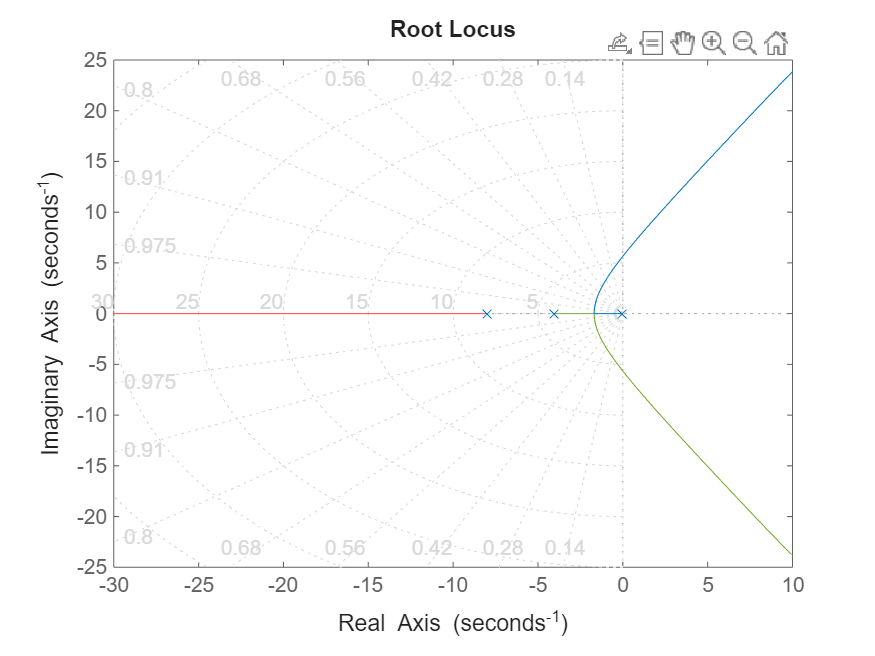

%L1.c. Stability Analysis

% Exercise 4(i)
% Obtain the root locus plot for
% G(s)=K/(s(s+4)(s+8))
% Find the stable range of K and break-away points

% Numerator coefficients
num=[1];
% Denominator coefficients
den=conv([1 0],[1 4]);
den=conv(den,[1 8]);
% Transfer function
G=tf(num,den);
% Root locus
figure(1)
rlocus(G)
grid on

% Gain and pole locations from root locus
[k,p]=rlocfind(G)

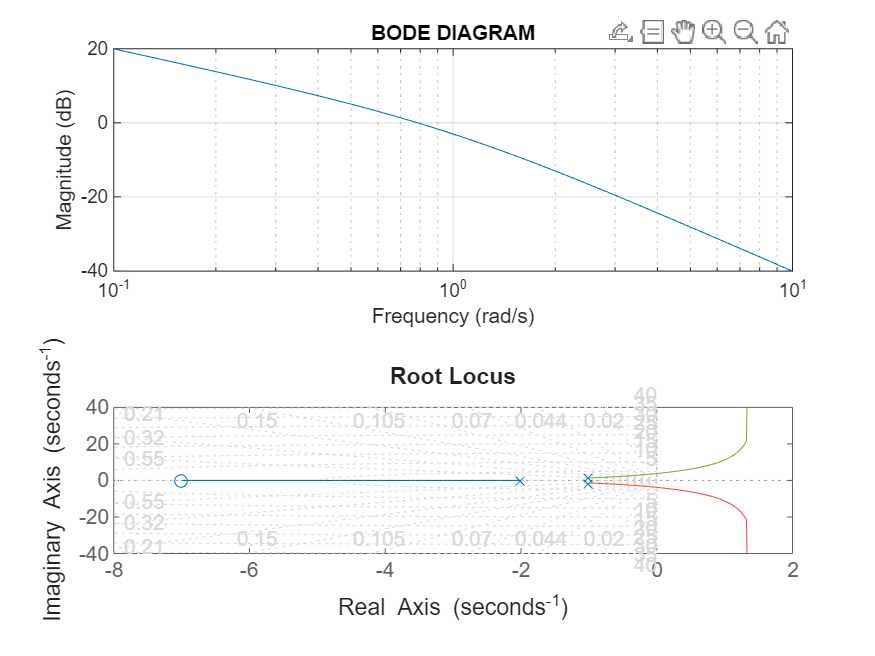

%L1.c. Stability Analysis

% Exercise 4(ii)
% Obtain the root locus plot for
% G(s)=K(s+7)/((s+2)(s^2+2s+3))
% Find the stable range of K and break-away points

% Numerator coefficients
num=[1 7];
% Denominator coefficients
den=conv([1 2],[1 2 3]);
% Transfer function
G=tf(num,den);
% Root locus
figure(1)
rlocus(G)
grid on

% Gain and pole locations from root locus
[k,p]=rlocfind(G)